**Author: Clara Vetter**

**Last modified: 25.01.2024**

addpath(genpath("/Users/claravetter/local/Code/NeuroMiner/NeuroMiner_Current"))
addpath("~/local/Code/mbSPLS/ScrFun_CV/")

# Test script for generalized spls with simulated data - small example

## Simulated data

rng(42);

% Number of samples and features
numSamples = 10;
numFeaturesX = 15;
numFeaturesY = 20;
numFeaturesZ = 10;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

## Define sPLS parameters

% Sparsity regularization parameters
cu = 3;
cv = 4;
cw = 2;

% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

## cv_generalized_spls

matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances,success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);

gs

## Hyperopt

- Q: what is the optimisation criterion in this case? How can we define which multi weight vectors maximize covariance in the case that n matrices > 2

% define range of cu, cv, cw for grid search 
cu_range = 1:1:sqrt(size(matrices{1},2));
cv_range = 1:1:sqrt(size(matrices{2},2));
cw_range = 1:1:sqrt(size(matrices{3},2));

% run grid search 
combi_idx_xyz = 0;
combi_idx_xy = 0;
result_table_xyz_gspls = array2table(zeros(length(cu_range)*length(cv_range)*length(cw_range),11), 'VariableNames',{'cu', 'cv', 'cw', 'corr_XY', 'corr_XZ', 'corr_YZ', 'spls_itr', 'diff', 'dim_m1', 'dim_m2', 'dim_m3'});
result_table_xy_spls = array2table(zeros(length(cu_range)*length(cv_range),7), 'VariableNames',{'cu', 'cv', 'corr_XY', 'spls_itr', 'diff', 'dim_m1', 'dim_m2'});
for i=1:length(cu_range)
    for j=1:length(cv_range)
        for k=1:length(cw_range)
            cu = cu_range(i);
            cv = cv_range(j);
            cw = cw_range(k);
            combi_idx_xyz = combi_idx_xyz+1;
            cs = [cu, cv, cw];
            % Run generalized SPLS
            [weights, covariances, success, spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);
            corr_XY = corr(matrices{1}*weights{1},matrices{2}*weights{2});
            corr_XZ = corr(matrices{1}*weights{1},matrices{3}*weights{3});
            corr_YZ = corr(matrices{2}*weights{2},matrices{3}*weights{3});
            result_table_xyz_gspls.cu(combi_idx_xyz) = cu; 
            result_table_xyz_gspls.cv(combi_idx_xyz) = cv; 
            result_table_xyz_gspls.cw(combi_idx_xyz) = cw; 
            result_table_xyz_gspls.corr_XY(combi_idx_xyz) = corr_XY;
            result_table_xyz_gspls.corr_XZ(combi_idx_xyz) = corr_XZ;
            result_table_xyz_gspls.corr_YZ(combi_idx_xyz) = corr_YZ;
            result_table_xyz_gspls.spls_itr(combi_idx_xyz) = spls_itr; 
            result_table_xyz_gspls.diff(combi_idx_xyz) = diff; 
            result_table_xyz_gspls.dim_m1(combi_idx_xyz) = dim_Ms(1);
            result_table_xyz_gspls.dim_m2(combi_idx_xyz) = dim_Ms(2);
            result_table_xyz_gspls.dim_m3(combi_idx_xyz) = dim_Ms(3);
        end
        combi_idx_xy = combi_idx_xy+1;
        [u, v, success, spls_itr, diff, dim_Ms] = cv_spls(Y, Z, cv, cw, e, itr_lim, 0); 
        corr_XY = corr(Y*u, Z*v); 
        result_table_xy_spls.cu(combi_idx_xy) = cu; 
        result_table_xy_spls.cv(combi_idx_xy) = cv;
        result_table_xy_spls.corr_XY(combi_idx_xy) = corr_XY;
        result_table_xy_spls.spls_itr(combi_idx_xy) = spls_itr;
        result_table_xy_spls.diff(combi_idx_xy) = diff;
        result_table_xy_spls.dim_m1(combi_idx_xy) = dim_Ms(1);
        result_table_xy_spls.dim_m2(combi_idx_xy) = dim_Ms(2);
    end
end

## Weight updating pairwise spls vs. gspls

cv = 2; 
cw = 4;
[u,v,success,spls_itr, diff, dim_Ms] = cv_spls(Y,Z, cv, cw, e, 10, 1);

% Sparsity regularization parameters
cu = 2;
cv = 4;
cw = 4;
cs = [cu, cv, cw];
[u,v,success,spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, 10, 1);

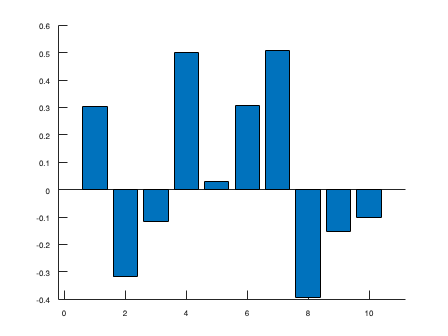

bar(weights{3})

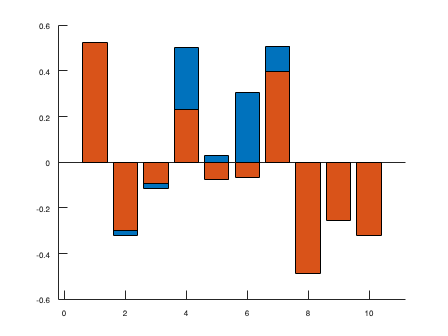

bar(v)

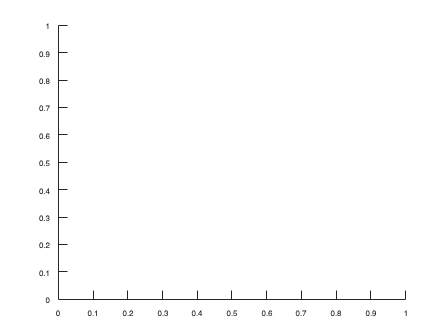

cla

weights{3}